# Train DDPG Agent

previousRngState = rng(0,"twister")

previousRngState = struct with fields:
     Type: 'twister'
     Seed: 0
    State: [625×1 uint32]


Ts = 2; % every Ts seconds, the RL agent makes an action
Tf = 80; % episode length is seconds

mdl = "MODEL_SS_withSCCandRL_Emily_Bus_Test";
open_system(mdl)

numAct = 4;
actInfo = rlNumericSpec([numAct 1],...
    'LowerLimit', -1*ones(numAct,1), ...
    'UpperLimit', ones(numAct,1));
actInfo.Name = 'Pagc';

% numObs = 8*3;
% obsInfo = rlNumericSpec([numObs 1],...
%     'LowerLimit', -1*[0.5/60*ones(4,1); ones(4,1); Inf*ones(16,1)], ...
%     'UpperLimit', 1*[0.5/60*ones(4,1); ones(4,1); Inf*ones(16,1)]);
% obsInfo.Name = 'f, Ptie, Sf, df, SPtie, dPtie,';
numObs = 6;
obsBus = Simulink.Bus();
obsBus.Elements(1) = Simulink.BusElement;
obsBus.Elements(1).Name = "obs1";
obsBus.Elements(1).Dimensions = [numObs,1];
obsBus.Elements(2) = Simulink.BusElement;
obsBus.Elements(2).Name = "obs2";
obsBus.Elements(2).Dimensions = [numObs,1];
obsBus.Elements(3) = Simulink.BusElement;
obsBus.Elements(3).Name = "obs3";
obsBus.Elements(3).Dimensions = [numObs,1];
obsBus.Elements(4) = Simulink.BusElement;
obsBus.Elements(4).Name = "obs4";
obsBus.Elements(4).Dimensions = [numObs,1];
obsInfo = bus2RLSpec("obsBus")

obsInfo = 1×4 rlNumericSpec array with properties:
    LowerLimit
    UpperLimit
    Name
    Description
    Dimension
    DataType



agentblk = mdl + "/RL Agent";
env = rlSimulinkEnv(mdl, agentblk, obsInfo, actInfo);

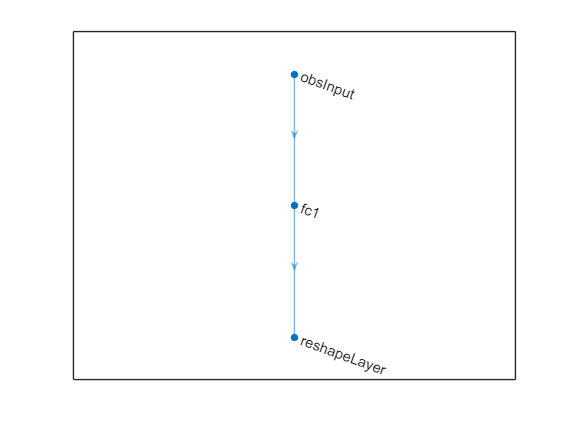

% Define the State Path
statePath = [
    featureInputLayer(24, Name="obsInput")     % Input layer with 24 features
    fullyConnectedLayer(24, 'Name', 'fc1')      % Fully connected layer to match size
    ChangeDimLayer('reshapeLayer', 6, 4)        % Custom reshaping layer to change size from 24x1 to 6x4
    ];

% Create the Layer Graph
lgraph = layerGraph(statePath);

% Visualize the layer graph
figure;
plot(lgraph);

analyzeNetwork(lgraph);


## Create Agent

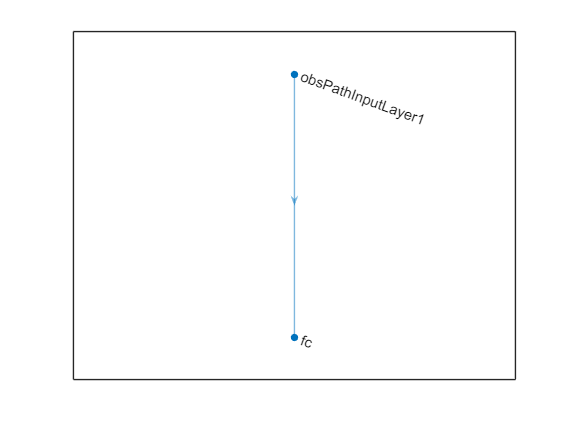

% Define state path
statePath1 = [
    featureInputLayer( ...
        numObs, ...
        Name="obsPathInputLayer1")
    fullyConnectedLayer(32)
    % reluLayer
    % fullyConnectedLayer(16,Name="spOutLayer1")
    ];

statePath2 = [
    featureInputLayer( ...
        numObs, ...
        Name="obsPathInputLayer2")
    % fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16,Name="spOutLayer2")
    ];

statePath3 = [
    featureInputLayer( ...
        numObs, ...
        Name="obsPathInputLayer3")
    % fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16,Name="spOutLayer3")
    ];


statePath4 = [
    featureInputLayer( ...
        numObs, ...
        Name="obsPathInputLayer4")
    % fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16,Name="spOutLayer4")
    ];
% Define action path
actionPath = [
    featureInputLayer( ...
        actInfo.Dimension(1), ...
        Name="actPathInputLayer")
    fullyConnectedLayer(16, ...
        Name="apOutLayer", ...
        BiasLearnRateFactor=0)
    ];

% Define common path
commonPath = [
    additionLayer(5,Name="add")
    reluLayer
    fullyConnectedLayer(8)
    reluLayer
    fullyConnectedLayer(1)
    ];

% Create layergraph, add layers and connect them
criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath1);
% criticNetwork = addLayers(criticNetwork,statePath2);
% criticNetwork = addLayers(criticNetwork,statePath4);
% criticNetwork = addLayers(criticNetwork,statePath3);
% criticNetwork = addLayers(criticNetwork,actionPath);
% criticNetwork = addLayers(criticNetwork,commonPath);
% criticNetwork = connectLayers(criticNetwork,"spOutLayer1","add/in1");
% criticNetwork = connectLayers(criticNetwork,"spOutLayer2","add/in2");
% criticNetwork = connectLayers(criticNetwork,"spOutLayer3","add/in3");
% criticNetwork = connectLayers(criticNetwork,"spOutLayer4","add/in4");
% criticNetwork = connectLayers(criticNetwork,"apOutLayer","add/in5");


% % Action Path
% actionPath = [
%     featureInputLayer(numAct, Name="actInput")
%     fullyConnectedLayer(50, Name="fc1b")
% ];
% 
% % Common Path
% commonPath = [
%     concatenationLayer(1, 2, Name="add")
%     reluLayer
%     fullyConnectedLayer(50, Name="fc2")
%     reluLayer
%     fullyConnectedLayer(1, Name="Q")
% ];
% 
% % Create a LayerGraph
% criticNetwork = layerGraph();
% 
% % Add the layers to the graph
% criticNetwork = addLayers(criticNetwork, statePath);
% criticNetwork = addLayers(criticNetwork, actionPath);
% criticNetwork = addLayers(criticNetwork, commonPath);
% 
% % Connect the layers
% criticNetwork = connectLayers(criticNetwork, "fc3a", "add/in1");
% criticNetwork = connectLayers(criticNetwork, "fc1b", "add/in2");

% Create the critic network
figure;
plot(criticNetwork);

analyzeNetwork(criticNetwork);

% Convert the LayerGraph to a dlnetwork
criticNetwork = dlnetwork(criticNetwork);

% Initialize and check the critic network
rng(0,"twister");
criticNet = initialize(criticNetwork);
summary(criticNetwork)


   Initialized: true

   Number of learnables: 224

   Inputs:
      1   'obsPathInputLayer1'   6 features




% Visualize the network
plot(criticNetwork);


% Define the Q-value function for RL
critic = rlQValueFunction(criticNetwork, ...
    [obsInfo(1), obsInfo(2), obsInfo(3), obsInfo(4)], actInfo, ...
    ObservationInputNames=["obsPathInputLayer1","obsPathInputLayer2","obsPathInputLayer3","obsPathInputLayer4"], ...
    ActionInputNames="actPathInputLayer");

Error using rl.internal.validate.mapFunctionObservationActionInput (line 10)
Number of input layers for state-action-value function deep neural network must equal the number of observation and action specifications.

Error in rlQValueFunction (line 118)
model = rl.internal.validate.mapFunc

% Define state path
statePath1 = [
    featureInputLayer( ...
        numObs, ...
        Name="obsPathInputLayer1")
    % fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16,Name="spOutLayer1")
    ];

statePath2 = [
    featureInputLayer( ...
        numObs, ...
        Name="obsPathInputLayer2")
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16,Name="spOutLayer2")
    ];

statePath3 = [
    featureInputLayer( ...
        numObs, ...
        Name="obsPathInputLayer3")
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16,Name="spOutLayer3")
    ];


statePath4 = [
    featureInputLayer( ...
        numObs, ...
        Name="obsPathInputLayer4")
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16,Name="spOutLayer4")
    ];
% Define common path
commonPath = [
    depthConcatenationLayer(4,Name="concat")
    tanhLayer
    ];

% Create layergraph, add layers and connect them
actorNetwork = layerGraph();
actorNetwork = addLayers(actorNetwork,statePath1);
actorNetwork = addLayers(actorNetwork,statePath2);
actorNetwork = addLayers(actorNetwork,statePath3);
actorNetwork = addLayers(actorNetwork,statePath4);
actorNetwork = addLayers(actorNetwork,commonPath);
actorNetwork = connectLayers(actorNetwork,"spOutLayer1","concat/in1");
actorNetwork = connectLayers(actorNetwork,"spOutLayer2","concat/in2");
actorNetwork = connectLayers(actorNetwork,"spOutLayer3","concat/in3");
actorNetwork = connectLayers(actorNetwork,"spOutLayer4","concat/in4");
plot(actorNetwork)
% actordlNet.Layers(2).Weights
actorNetwork = dlnetwork(actorNetwork);
summary(actorNetwork)
plot(layerGraph(actorNetwork));

actor = rlContinuousDeterministicActor(actorNet, ...
    [obsInfo(1), obsInfo(2), obsInfo(3), obsInfo(4)], actInfo, ...
    ObservationInputNames=["obsPathInputLayer1","obsPathInputLayer2","obsPathInputLayer3","obsPathInputLayer4"]);

criticOpts = rlOptimizerOptions(LearnRate=1e-03,GradientThreshold=1);
actorOpts = rlOptimizerOptions(LearnRate=1e-04,GradientThreshold=1);
agentOpts = rlDDPGAgentOptions(...
    SampleTime=Ts,...
    CriticOptimizerOptions=criticOpts,...
    ActorOptimizerOptions=actorOpts,...
    ExperienceBufferLength=1e6,...
    DiscountFactor=0.999,...
    MiniBatchSize=64);
agentOpts.NoiseOptions.StandardDeviation = 0.1;
agentOpts.NoiseOptions.StandardDeviationDecayRate = 1e-5;

agent = rlDDPGAgent(actor,critic,agentOpts);

## Train Agent

maxepisodes = 1000;
maxsteps = ceil(Tf/Ts);
trainOpts = rlTrainingOptions(...
    MaxEpisodes=maxepisodes,...
    MaxStepsPerEpisode=maxsteps,...
    ScoreAveragingWindowLength=100,...
    Verbose=false,...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    StopTrainingValue=1e3);
rng(0,"twister");

doTraining = true;
if doTraining
    trainResult = train(agent, env, trainOpts);
end

## Simulate Agent

sim(mdl);

saveResults = true;
if saveResults
    % Save the training result to a .mat file
    save('v10RLTrainResults.mat', 'trainResult');
    
    save('v10RLAgent.mat', 'agent');
end